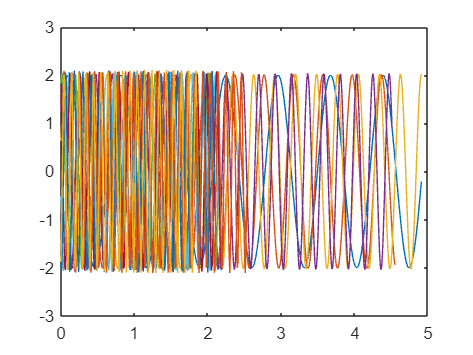

%import dos dados
time_x = {senf020a200Ent_Time, senf060a200Ent_Time, senf500a200Ent_Time, senf550a200Ent_Time, senf600a200Ent_Time, senf650a200Ent_Time, senf700a200Ent_Time, senf750a200Ent_Time, senf800a200Ent_Time, senf850a200Ent_Time, senf900a200Ent_Time, senf950a200Ent_Time, senf1000a200Ent_Time};
time_y = {senf020a200Sai_Time(:,1), senf060a200Sai_Time(:,1), senf500a200Sai_Time(:,1), senf550a200Sai_Time(:,1), senf600a200Sai_Time(:,1), senf650a200Sai_Time(:,1), senf700a200Sai_Time(:,1), senf750a200Sai_Time(:,1), senf800a200Sai_Time(:,1), senf850a200Sai_Time(:,1), senf900a200Sai_Time(:,1), senf950a200Sai_Time(:,1), senf1000a200Sai_Time(:,1)};

x = {senf020a200Ent_Value, senf060a200Ent_Value, senf500a200Ent_Value, senf550a200Ent_Value, senf600a200Ent_Value, senf650a200Ent_Value, senf700a200Ent_Value, senf750a200Ent_Value, senf800a200Ent_Value, senf850a200Ent_Value, senf900a200Ent_Value, senf950a200Ent_Value, senf1000a200Ent_Value};
y = {senf020a200Sai_Value(:,1), senf060a200Sai_Value(:,1), senf500a200Sai_Value(:,1), senf550a200Sai_Value(:,1), senf600a200Sai_Value(:,1), senf650a200Sai_Value(:,1), senf700a200Sai_Value(:,1), senf750a200Sai_Value(:,1), senf800a200Sai_Value(:,1), senf850a200Sai_Value(:,1), senf900a200Sai_Value(:,1), senf950a200Sai_Value(:,1), senf1000a200Sai_Value(:,1)};
% 
% time_x = {ent_sen_2_1_Time, ent_sen_2_2_Time, ent_sen_2_3_Time, ent_sen_2_4_Time, ent_sen_2_5_Time, ent_sen_2_6_Time, ent_sen_2_7_Time, ent_sen_2_8_Time, ent_sen_2_9_Time, ent_sen_2_10_Time};
% time_y = {sai_sen_2_1_Time(:,1), sai_sen_2_2_Time(:,1), sai_sen_2_3_Time(:,1), sai_sen_2_4_Time(:,1), sai_sen_2_5_Time(:,1), sai_sen_2_6_Time(:,1), sai_sen_2_7_Time(:,1), sai_sen_2_8_Time(:,1), sai_sen_2_9_Time(:,1), sai_sen_2_10_Time(:,1)};
% 
% x = {ent_sen_2_1_Value, ent_sen_2_2_Value, ent_sen_2_3_Value, ent_sen_2_4_Value, ent_sen_2_5_Value, ent_sen_2_6_Value, ent_sen_2_7_Value, ent_sen_2_8_Value, ent_sen_2_9_Value, ent_sen_2_10_Value};
% y = {sai_sen_2_1_Value(:,1), sai_sen_2_2_Value(:,1), sai_sen_2_3_Value(:,1), sai_sen_2_4_Value(:,1), sai_sen_2_5_Value(:,1), sai_sen_2_6_Value(:,1), sai_sen_2_7_Value(:,1), sai_sen_2_8_Value(:,1), sai_sen_2_9_Value(:,1), sai_sen_2_10_Value(:,1)};

%numerando os graficos de interesse
graf_init = 1;
graf_end = 13;
% graf_end = 10;

%plot do gráfico todo
for i = graf_init:graf_end
    time_x{i}= time_x{i}-time_x{i}(1);
    plot(time_x{i},x{i})
    hold on
end
hold off

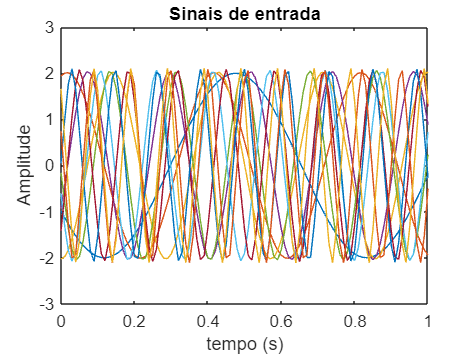

%definindo novas matrizes inputs
range_time_x = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_x = zeros(length(0:0.01:1), graf_end-graf_init+1);

%Pegando o ultimo segundo de cada  inputs
for i = graf_init:graf_end
    for j = 0:100
        range_time_x(j+1, i)= time_x{i}(length(time_x{i})-100+j)-time_x{i}(length(time_x{i})-100);
        range_x(j+1, i)= x{i}(length(time_x{i})-100+j);
    end
end

%definindo novas matrizes outputs
range_time_y = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_y = zeros(length(0:0.01:1), graf_end-graf_init+1);

%Pegando o ultimo segundo de cada  outputs
for i = graf_init:graf_end
    for j = 0:100
        range_time_y(j+1, i)= time_y{i}(length(time_y{i})-100+j)-time_y{i}(length(time_y{i})-100);
        range_y(j+1, i)= y{i}(length(time_y{i})-100+j);
    end
end

%Plotando esse ultimo segundo
plot(range_time_x(:,:),range_x(:,:))
title("Sinais de entrada")
xlabel("tempo (s)")
ylabel("Amplitude")

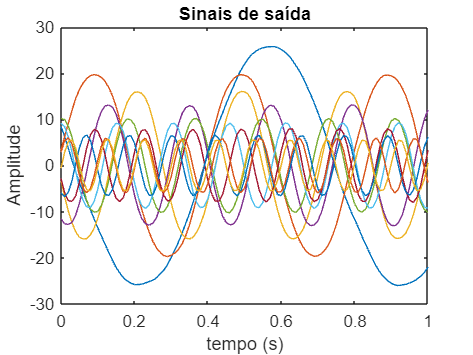


plot(range_time_y(:,:),range_y(:,:))
title("Sinais de saída")
xlabel("tempo (s)")
ylabel("Amplitude")

%fft dos sinais de entrada e saída
x_mx_fft = fft(range_x);
y_mx_fft = fft(range_y);

%Pegando os picos de cada sinal
[x_max, x_ind] = max(abs(x_mx_fft));
[y_max, y_ind] = max(abs(y_mx_fft));

x_angle_max = angle(x_mx_fft(x_ind));
y_angle_max = angle(y_mx_fft(y_ind));

phaseResponse2 = y_angle_max - x_angle_max

phaseResponse2 =     5.6688   -1.2491   -1.6528   -1.8994   -2.0056   -2.0949   -2.2133   -2.3590   -2.3137   -2.3137



magnitudeResponse2 = y_max./x_max

magnitudeResponse2 =    12.1503    9.5037    7.3001    7.0420    5.5691    4.9597    3.9402    3.4596    3.0391    2.8443


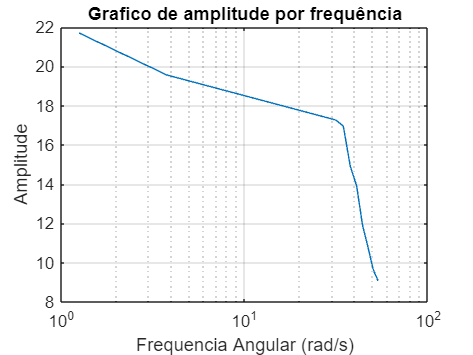

%frequências medidas
%frequencySample
frequencies = [0.2, 0.6, 5, 5.5, 6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5, 10];

%omega e amplitude
omega2 = zeros(1, graf_end-graf_init+1);
ampl2 = zeros(1, graf_end-graf_init+1);


for i = graf_init:graf_end
    omega2(i) = 2*pi*frequencies(1,i);
    ampl2(i) = 20*log10(magnitudeResponse2(1,i));
end

%plot em escala logaritimica
semilogx(omega2,ampl2,'-')
title('Grafico de amplitude por frequência');
xlabel ('Frequencia Angular (rad/s)') ;
ylabel("Amplitude")

grid on

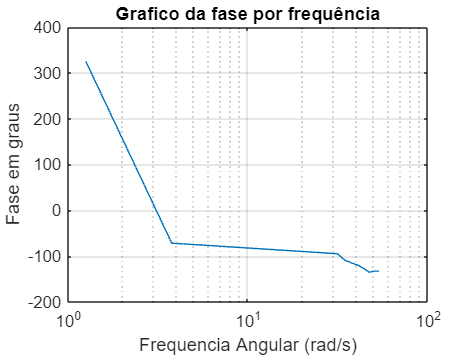


%fase
fase2 = zeros(1, graf_end-graf_init+1);

for i = graf_init:graf_end
    fase2(i) = phaseResponse2(i);
end

%plot em escala logaritimica
semilogx(omega2, rad2deg(fase2))
title('Grafico da fase por frequência');
xlabel ('Frequencia Angular (rad/s)') ;
ylabel("Fase em graus")

grid on

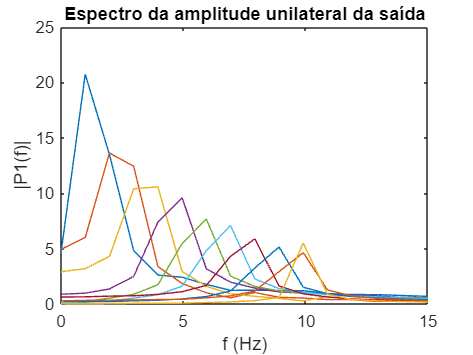

%tamanho do sinal
N = length(y_mx_fft(:,1));

%preparando os multiplos das frequencias
frequencySample = 1/0.01;
frequenciesSample = frequencySample*(0:(N/2))/N;

%Metade do grafico
P2 = abs(y_mx_fft/N);
P1 = P2(1:floor(N/2)+1,:);
P1(2:end-1) = 2*P1(2:end-1);

for i = graf_init:graf_end
    plot(frequenciesSample,P1(:,i))
    hold on
end
hold off

title("Espectro da amplitude unilateral da saída")
xlabel("f (Hz)")
ylabel("|P1(f)|")
xlim([0 15])